# **IJC Template**

## Model Initialization

Model parameters

dt = 1e-3;

# TASK 1

## Model the motor in the block diagram in Fig. 2 using Simulink

Motor parameters

Ra  = 0.3; % ohm
Jm  = 6;   % Kg.m^2
Kv  = 0.5; % V.s/rad
Kt  = 0.5; % N.m/A

# TASK 2

## Add the amplifier (which is the gain $G_v$) and create the control voltage signal $V_c$

clc
close all

Gv = 1; % Amplifier gain

Closed loop transfer function from input to the motor position. You can the Matlab command "tf" to compute your transfer functions.

s=tf('s');
Small_loop_f=Kt/(Ra*Jm*s);
Small_loop=Small_loop_f/(1+Kv*Small_loop_f);
Small_loop=minreal(Small_loop)

Small_loop =
 
    0.2778
  ----------
  s + 0.1389
 
Continuous-time transfer function.



TF_input= (Gv*Small_loop/s)/(1+(Gv*Small_loop/s));
TF_input=minreal(TF_input)

TF_input =
 
          0.2778
  -----------------------
  s^2 + 0.1389 s + 0.2778
 
Continuous-time transfer function.



TF_input = (Gv*Kt)/((Ra*Jm*s+Kt*Kv)*s+Gv*Kt)% <YOUR_CODE_HERE>

TF_input =
 
           0.5
  ----------------------
  1.8 s^2 + 0.25 s + 0.5
 
Continuous-time transfer function.



TF_input = minreal(TF_input)

TF_input =
 
          0.2778
  -----------------------
  s^2 + 0.1389 s + 0.2778
 
Continuous-time transfer function.



Transfer function from disturbance to theta

TF_dist  = 1/(Jm*s^2+(Kv*Kt*s)/Ra+(Gv*Kt)/Ra)% <YOUR_CODE_HERE>

TF_dist =
 
           0.3
  ----------------------
  1.8 s^2 + 0.25 s + 0.5
 
Continuous-time transfer function.



TF_dist=minreal(TF_dist)

TF_dist =
 
          0.1667
  -----------------------
  s^2 + 0.1389 s + 0.2778
 
Continuous-time transfer function.



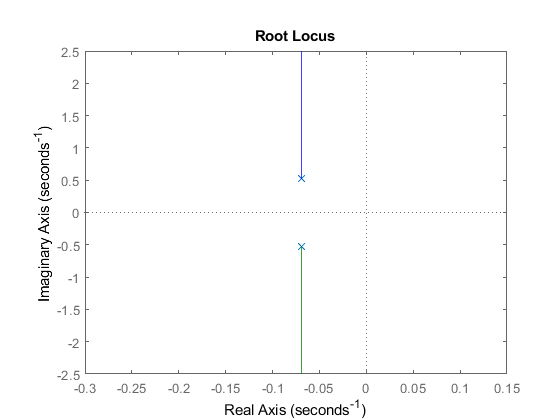

rlocus(TF_dist)

rlocus(TF_input)

# TASK 3 

## Improve the system performance using a PI controller 

Controller gains

ki   = 1; % <YOUR_CODE_HERE>
kp   = 100; % <YOUR_CODE_HERE>
K    = 1;

Controller transfer functions

% G_PI = controller in forward path
G_PI = kp+ki/s; % <YOUR_CODE_HERE>
Gc   = G_PI;
Big_loop_f=Gc*Gv*Small_loop/s;
Big_loop=Big_loop_f/(1+Big_loop_f*K);
Big_loop=minreal(Big_loop);

Gm   = Gv*Small_loop/s;

Root Locus

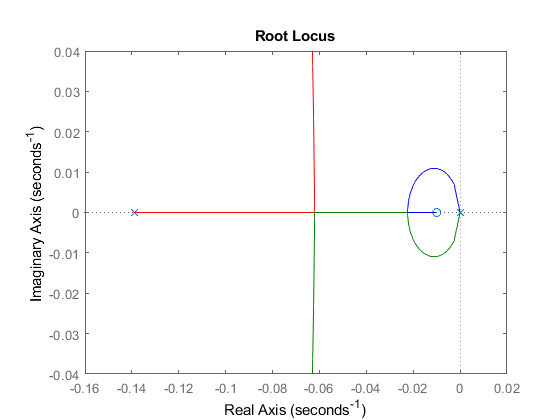

close all
figure
rlocus(Gc*Gm)

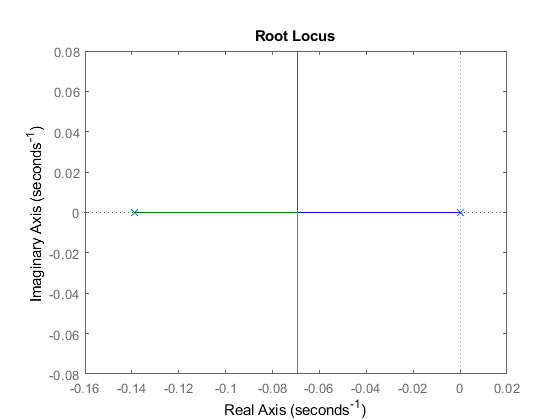

rlocus(Gm)

# TASK 4

## Independet joint control of the two-link robot arm

D-Control gains

kd1 = 50; % <YOUR_CODE_HERE>
kd2 = 25; % <YOUR_CODE_HERE>

Link paremeters

m1    = 1;
m2    = 1;
l1    = 1; 
lc1   = l1/2 ;
l2    = 1;
lc2   = l2/2;
h1    = 0.1;
delta = 0.05;
g     = 9.81;